alpha=1+mod(109,3);

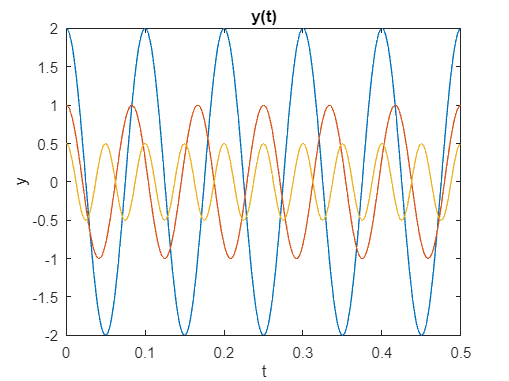

t = 0:0.001:0.5;
y1 = alpha*cos(5*alpha*t*2*pi);
plot(t,y1)
hold on
xlabel('t'); 
ylabel ('y');
title('y(t)');
y2=alpha/2*cos(6*alpha*t*2*pi);
plot(t,y2)
hold on
y3=alpha/4*cos(10*alpha*t*2*pi);
plot(t,y3)
hold off

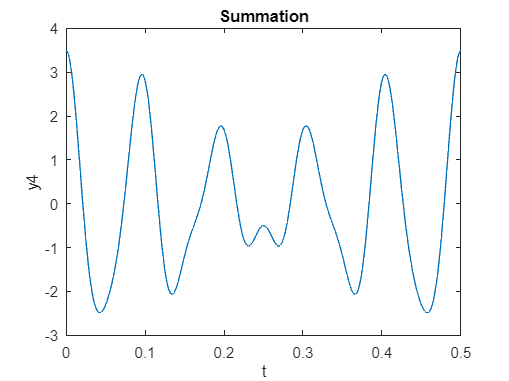

%2
figure;
y4=y1+y2+y3;
plot(t,y4)
xlabel('t'); 
ylabel ('y4');
title('Summation');

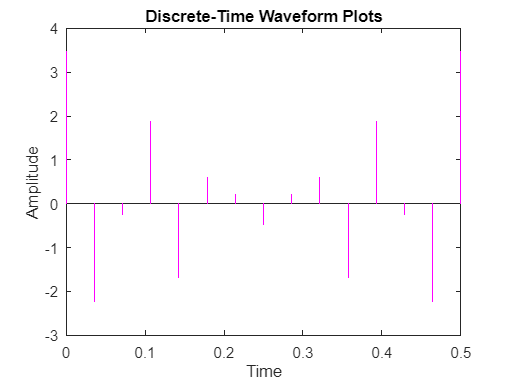

%3
% Define the parameters
duration = 1/alpha;
Fs = 14*alpha; % Sampling frequency
t1 = 0:1/Fs:duration;
y1 = alpha*cos(5*alpha*t1*2*pi);
y2=alpha/2*cos(6*alpha*t1*2*pi);
y3=alpha/4*cos(10*alpha*t1*2*pi);
y4=y1+y2+y3;
figure;

stem(t1, y4, 'm', 'Marker', 'none')
title('Discrete-Time Summation of Waveforms');
xlabel('Time');
ylabel('Amplitude');
title('Discrete-Time Waveform Plots');

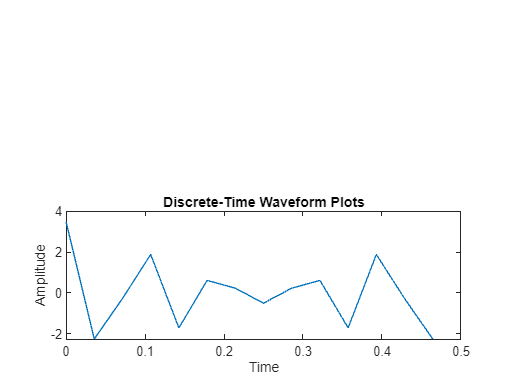

t1 = 0:1/Fs:duration-1/Fs;
y1 = alpha*cos(5*alpha*t1*2*pi);
y2=alpha/2*cos(6*alpha*t1*2*pi);
y3=alpha/4*cos(10*alpha*t1*2*pi);
y4=y1+y2+y3;
figure;
subplot(2, 1, 2);
stem(t1, y4, 'm', 'Marker', 'none')
plot(t1,y4)
xlabel('Time');
ylabel('Amplitude');
title('Discrete-Time Waveform Plots');

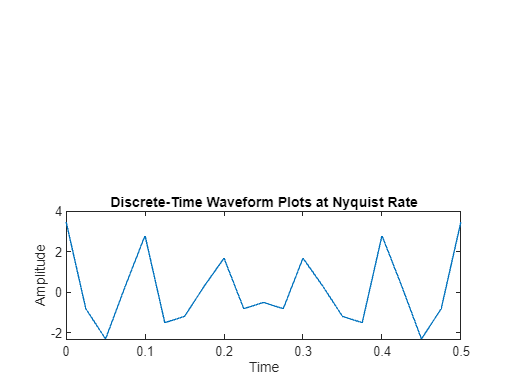

%3b
% Define the parameters
alpha = 2;
duration = 1/alpha;
Nyquist_rate = 20*alpha; % Nyquist rate
t = 0:1/Nyquist_rate:duration;

% Waveforms
y1 = alpha*cos(5*alpha*t*2*pi);
y2=alpha/2*cos(6*alpha*t*2*pi);
y3=alpha/4*cos(10*alpha*t*2*pi);
y4=y1+y2+y3;
figure;

% Plot discrete-time waveforms using stem
subplot(2, 1, 2);
stem(t, y4, 'm', 'Marker', 'none');
plot(t,y4)
xlabel('Time');
ylabel('Amplitude');
title('Discrete-Time Waveform Plots at Nyquist Rate');

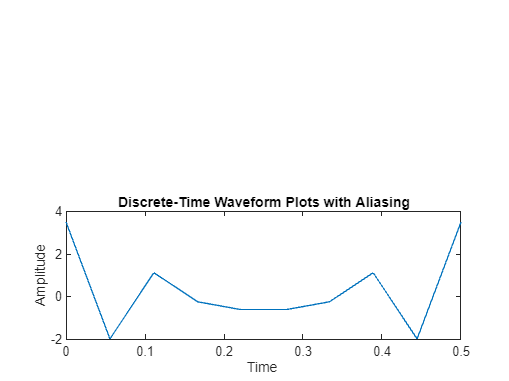

%3c
% Define the parameters
alpha = 2;
duration = 1/alpha;
sampling_rate = 9*alpha; % Required sampling rate for aliasing
t = 0:1/sampling_rate:duration;
% Waveforms
y1 = alpha*cos(5*alpha*t*2*pi);
y2=alpha/2*cos(6*alpha*t*2*pi);
y3=alpha/4*cos(10*alpha*t*2*pi);
y4=y1+y2+y3;
figure;


subplot(2, 1, 2);
stem(t,y4, 'm', 'Marker', 'none');
plot(t,y4)
xlabel('Time ');
ylabel('Amplitude');
title('Discrete-Time Waveform Plots with Aliasing');

% Linear interpolation
t_interpolate = linspace(0, 1/alpha, 10000); % Interpolation points
interp_signal_a = interp1(n_a, signal_a, t_interpolate, 'linear');

Unrecognized function or variable 'n_a'.

interp_signal_b = interp1(n_b, signal_b, t_interpolate, 'linear');
interp_signal_c = interp1(n_c, signal_c, t_interpolate, 'linear');

% Plotting
figure;
subplot(3,1,1);
plot(t_continuous, total_waveform, 'b', 'LineWidth', 1.5);
hold on;
plot(t_interpolate, interp_signal_a, 'r--', 'LineWidth', 1.5);
hold off;
title('Reconstructed Signal at Fs = 14\alpha samples/second');
xlabel('Time (seconds)');
ylabel('Amplitude');
legend('Original Signal', 'Interpolated Signal');
grid on;

subplot(3,1,2);
plot(t_continuous, total_waveform, 'b', 'LineWidth', 1.5);
hold on;
plot(t_interpolate, interp_signal_b, 'r--', 'LineWidth', 1.5);
hold off;
title('Reconstructed Signal at Nyquist Rate');
xlabel('Time (seconds)');
ylabel('Amplitude');
legend('Original Signal', 'Interpolated Signal');
grid on;

subplot(3,1,3);
plot(t_continuous, total_waveform, 'b', 'LineWidth', 1.5);
hold on;
plot(t_interpolate, interp_signal_c, 'r--', 'LineWidth', 1.5);
hold off;
title('Reconstructed Signal with Aliasing');
xlabel('Time (seconds)');
ylabel('Amplitude');
legend('Original Signal', 'Interpolated Signal');
grid on;

sgtitle('Reconstructed Waveforms using Linear Interpolation');




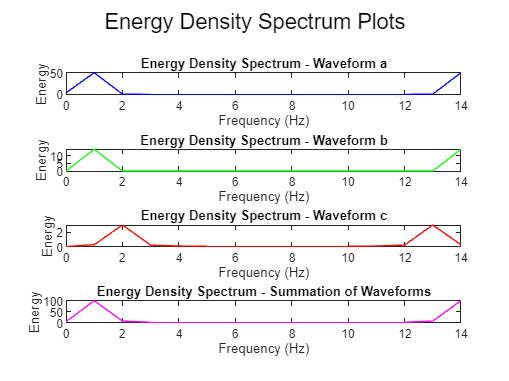

%5
% Define the parameters
alpha = 1;
duration = 1/alpha;
Fs = 14*alpha; % Sampling frequency
t = 0:1/Fs:duration;

% Waveforms
waveform_a = alpha * cos(5*alpha*t);
waveform_b = (alpha/2) * cos(6*alpha*t);
waveform_c = (alpha/4) * cos(10*alpha*t);
total_waveform = waveform_a + waveform_b + waveform_c;

% Compute the FFT
N = length(t);
frequencies = linspace(0, Fs, N);
fft_waveform_a = fft(waveform_a);
fft_waveform_b = fft(waveform_b);
fft_waveform_c = fft(waveform_c);
fft_total_waveform = fft(total_waveform);

% Plot energy density spectrum
figure;
subplot(4, 1, 1);
plot(frequencies, abs(fft_waveform_a).^2, 'b');
title('Energy Density Spectrum - Waveform a');
xlabel('Frequency (Hz)');
ylabel('Energy');

subplot(4, 1, 2);
plot(frequencies, abs(fft_waveform_b).^2, 'g');
title('Energy Density Spectrum - Waveform b');
xlabel('Frequency (Hz)');
ylabel('Energy');

subplot(4, 1, 3);
plot(frequencies, abs(fft_waveform_c).^2, 'r');
title('Energy Density Spectrum - Waveform c');
xlabel('Frequency (Hz)');
ylabel('Energy');

subplot(4, 1, 4);
plot(frequencies, abs(fft_total_waveform).^2, 'm');
title('Energy Density Spectrum - Summation of Waveforms');
xlabel('Frequency (Hz)');
ylabel('Energy');

sgtitle('Energy Density Spectrum Plots');


% Identifying aliased frequencies
aliased_frequency_a = 2*alpha - 5*alpha;
aliased_frequency_c = 2*alpha - 10*alpha;

fprintf('Aliased Frequency in Waveform a: %.2f Hz (aliases 5*alpha Hz)\n', aliased_frequency_a);

Aliased Frequency in Waveform a: -3.00 Hz (aliases 5*alpha Hz)


fprintf('Aliased Frequency in Waveform c: %.2f Hz (aliases 10*alpha Hz)\n', aliased_frequency_c);

Aliased Frequency in Waveform c: -8.00 Hz (aliases 10*alpha Hz)


%problem 3
% Load the original audio file
original_filename = 'Track002.wav';
[x, original_fs] = audioread(original_filename);

% Play the original audio
sound(x, original_fs);

% Downsampling with different rates
downsample_factors = [2, 3, 4]; % For example, downsampling by half, one-third, one-fourth
for factor = downsample_factors
    downsampled_filename = sprintf('downsampled_%d.wav', factor);
    downsampled_signal = downsample(x, factor);
    downsampled_fs = original_fs / factor;
    
    % Save the downsampled audio as a .wav file
    audiowrite(downsampled_filename, downsampled_signal, downsampled_fs);
    
    % Play the downsampled audio
    sound(downsampled_signal, downsampled_fs);
    pause(length(downsampled_signal) / downsampled_fs); % Wait for playback to finish
end


% Upsampling while preserving frequency content
desired_upsample_factor = 2; % For example, upsampling by a factor of 2
upsampled_signal = resample(x, desired_upsample_factor, 1);
upsampled_fs = original_fs * desired_upsample_factor;

% Save the upsampled audio as a .wav file
upsampled_filename = sprintf('upsampled_%d.wav', desired_upsample_factor);
audiowrite(upsampled_filename, upsampled_signal, upsampled_fs);

% Play the upsampled audio
sound(upsampled_signal, upsampled_fs);
pause(length(upsampled_signal) / upsampled_fs); % Wait for playback to finish
